clear;
m1=-1;
m2=1;
N=1000;

var1=0.25;
var2=0.49;
var3=1.00;

x11=sqrt(var1)*randn(1,N)+m1;
x12=sqrt(var1)*randn(1,N)+m2;
x1=[x11 x12];

x21=sqrt(var2)*randn(1,N)+m1;
x22=sqrt(var2)*randn(1,N)+m2;
x2=[x21 x22];

x31=sqrt(var3)*randn(1,N)+m1;
x32=sqrt(var3)*randn(1,N)+m2;
x3=[x31 x32];

Oppgave 1

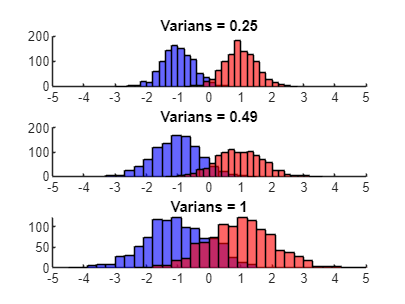

figure;
subplot(3,1,1);
hold on
histogram(x11,'FaceColor','b');
histogram(x12,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var1);

subplot(3,1,2);
hold on
histogram(x21,'FaceColor','b');
histogram(x22,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var2);

subplot(3,1,3);
hold on
histogram(x31,'FaceColor','b');
histogram(x32,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var3);

% True Error rates
True_Pe1=erfc(-m1/sqrt(var1)); disp("True P_e1: "+True_Pe1);

True P_e1: 0.0046777


True_Pe2=erfc(-m1/sqrt(var2)); disp("True P_e2: "+True_Pe2);

True P_e2: 0.043352


True_Pe3=erfc(-m1/sqrt(var3)); disp("True P_e3: "+True_Pe3);

True P_e3: 0.1573


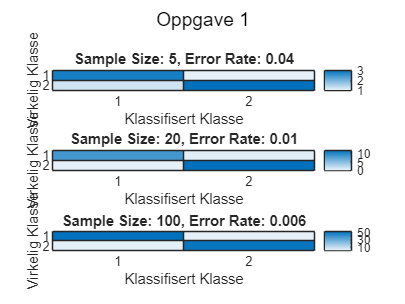

% Error rates, for different sample sizes.
N_T = [5 20 100];
num_experiments = 5;
exp_set=x1; %Bytt mellom x1, x2 og x3

% Initialize variables for confusion matrices and error rates
confusion_matrices = zeros(2, 2, num_experiments, numel(N_T));
error_rates = zeros(num_experiments, numel(N_T));
true_labels = [ones(1, N), 2 * ones(1, N)];

for exp_idx = 1:num_experiments
    for nt_idx = 1:numel(N_T)
        % Sample from combined data
        sample_indices = randperm(numel(exp_set), N_T(nt_idx));
        samples = exp_set(sample_indices);
        
        % Predict which class each sample belongs to
        predicted_labels = (abs(samples - m1) > abs(samples - m2)) + 1;
        
        % Compute confusion matrix
        confusion_matrix = confusionmat(true_labels(sample_indices), predicted_labels);
        confusion_matrices(:, :, exp_idx, nt_idx) = confusion_matrix;
        
        % Compute error rate
        % Compare true labels with predicted labels
        is_correct = (true_labels(sample_indices) == predicted_labels);
        error_rate = sum(~is_correct) / numel(is_correct);
        error_rates(exp_idx, nt_idx) = error_rate;
    end
end

% Average confusion matrices
avg_confusion_matrices = mean(confusion_matrices, 3);

% Average error rates
avg_error_rates = mean(error_rates, 1);

% Visualiser Average Confusion Matrices som Heatmaps
figure;
sgtitle("Oppgave 1");
for nt_idx = 1:numel(N_T)
    % Retrieve the average confusion matrix and error rate for the current sample size
    avg_confusion_matrix = avg_confusion_matrices(:, :, nt_idx);
    avg_error_rate = avg_error_rates(nt_idx);

    subplot(numel(N_T), 1, nt_idx);
    heatmap(avg_confusion_matrix);
    % Add title and axis labels
    title("Sample Size: " + N_T(nt_idx) + ", Error Rate: " + avg_error_rate);
    xlabel('Klassifisert Klasse');
    ylabel('Virkelig Klasse');
end

Oppgave 2

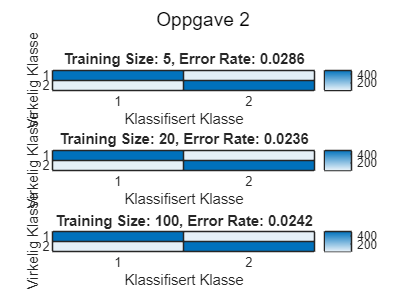

exp_set=x1; %Bytt mellom x1, x2 og x3
train_set1=exp_set(1:500); 
train_set2=exp_set(1001:1500);
test_set=[exp_set(501:1000) exp_set(1501:end)];
true_labels = [ones(1, 500), 2 * ones(1, 500)];

N_D=[5 20 100];
num_experiments = 5;

confusion_matrices = zeros(2, 2, num_experiments, numel(N_D));
error_rates = zeros(num_experiments, numel(N_D));

for exp_idx = 1:num_experiments
    for nd_idx = 1:numel(N_D)
        % Predict which class each sample belongs to
        sample_indices = 1+(exp_idx-1)*N_D(nd_idx):exp_idx*N_D(nd_idx);

        Dm1=mean(train_set1(sample_indices));
        Dm2=mean(train_set2(sample_indices));

        predicted_labels = (abs(test_set - Dm1) > abs(test_set - Dm2)) + 1;
        
        % Compute confusion matrix
        confusion_matrix = confusionmat(true_labels, predicted_labels);
        confusion_matrices(:, :, exp_idx, nd_idx) = confusion_matrix;
        
        % Compute error rate
        % Compare true labels with predicted labels
        is_correct = (true_labels == predicted_labels);
        error_rate = sum(~is_correct) / numel(is_correct);
        error_rates(exp_idx, nd_idx) = error_rate;
    end
end

% Average confusion matrices
avg_confusion_matrices = mean(confusion_matrices, 3);

% Average error rates
avg_error_rates = mean(error_rates, 1);

figure;
sgtitle("Oppgave 2");
for nd_idx = 1:numel(N_D)
    % Retrieve the average confusion matrix and error rate for the current training set size
    avg_confusion_matrix = avg_confusion_matrices(:, :, nd_idx);
    avg_error_rate = avg_error_rates(nd_idx);
 
    subplot(numel(N_D), 1, nd_idx);
    heatmap(avg_confusion_matrix);
    title("Training Size: " + N_D(nd_idx) + ", Error Rate: " + avg_error_rate);
    xlabel('Klassifisert Klasse');
    ylabel('Virkelig Klasse');
end

Oppgave 3

nSamples=6;
exp_set=x1; %Bytt mellom x1, x2 og x3
train_set=[exp_set(1:nSamples) exp_set(1001:1000+nSamples)];
test_set=[exp_set(501:500+nSamples) exp_set(1501:1500+nSamples)];
true_labels=[ones(1:nSamples), ones(1:nSamples)*2];

for idx = 1:nSamples
%fortsettelse følger....
end